addpath(genpath(pwd));

if ~license('test', 'communication_toolbox')
    error('Communications Toolbox is required.');
end

ofdmParams = ofdm_config();
channelParams = channel_config();

textMessage = 'Complete OFDM simulation test run.';

% --- Передатчик ---
% 1. Знаковое кодирование
encodedBits = symbolEncoder(textMessage);
% 2. Сверточное кодирование
convEncodedBits = convolutionalEncoder(encodedBits);
% 3. Прямое перемежение
interleavedBits = interleaver(convEncodedBits);
% 4. QPSK модуляция
modulatedSymbols = qpskModulator(interleavedBits);
% 5. OFDM модуляция
ofdmSymbol = ofdmModulator(modulatedSymbols, ofdmParams);

% --- Канал ---
receivedSignal = multipathChannel(ofdmSymbol, channelParams);
disp('Signal transmission through channel complete.');

Signal transmission through channel complete.




% --- Приемник ---
% 6. OFDM демодуляция и эквалайзация
qpskSymbolsReceived = ofdmDemodulator(receivedSignal);
disp('OFDM Demodulation and Equalization complete.');

OFDM Demodulation and Equalization complete.



% 7. QPSK демодуляция
demodulatedBits = qpskDemodulator(qpskSymbolsReceived);

% 8. Обратное перемежение
deinterleavedBits = deinterleaver(demodulatedBits);

% 9. Декодирование Витерби
decodedBits = viterbiDecoder(deinterleavedBits);

% 10. Знаковое декодирование
decodedMessage = symbolDecoder(decodedBits);

if isequal(textMessage, decodedMessage)
    disp('-----------------------------------------------------');
    disp('Test PASSED: Message decoded successfully!');
    disp(['Original Message:  ', textMessage]);
    disp(['Decoded Message:   ', decodedMessage]);
    disp('-----------------------------------------------------');
else
    disp('-----------------------------------------------------');
    disp('Test FAILED: Decoded message does not match original.');
    disp(['Original Message:  ', textMessage]);
    disp(['Decoded Message:   ', decodedMessage]);
    ber = sum(encodedBits(1:length(decodedBits)) ~= decodedBits) / length(decodedBits); % Примерный BER до знакового декодера
    disp(['Approximate BER before symbol decoder: ', num2str(ber)]);
    disp('-----------------------------------------------------');
end

-----------------------------------------------------


Test PASSED: Message decoded successfully!


Original Message:  Complete OFDM simulation test run.


Decoded Message:   Complete OFDM simulation test run.


-----------------------------------------------------


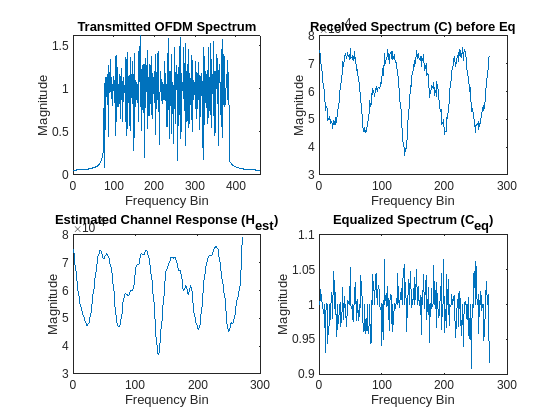


figure;
subplot(2,2,1); plot(abs(fft(ofdmSymbol))); title('Transmitted OFDM Spectrum'); xlabel('Frequency Bin'); ylabel('Magnitude');
ofdmSpectrum_C = getappdata(0, 'ofdmSpectrum_C');
if ~isempty(ofdmSpectrum_C)
    subplot(2,2,2); plot(abs(ofdmSpectrum_C)); title('Received Spectrum (C) before Eq'); xlabel('Frequency Bin'); ylabel('Magnitude');
end
channelEstimate_H_interp = getappdata(0, 'channelEstimate_H_interp');
if ~isempty(channelEstimate_H_interp)
    subplot(2,2,3); plot(abs(channelEstimate_H_interp)); title('Estimated Channel Response (H_{est})'); xlabel('Frequency Bin'); ylabel('Magnitude');
end
equalizedSpectrum_Ceq = getappdata(0, 'equalizedSpectrum_Ceq');
if ~isempty(equalizedSpectrum_Ceq)
    subplot(2,2,4); plot(abs(equalizedSpectrum_Ceq)); title('Equalized Spectrum (C_{eq})'); xlabel('Frequency Bin'); ylabel('Magnitude');
end